# Test Case - Motor Drive Unit

mdl = "MotorDriveUnit_Component_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end
MotorDriveUnit_Component_harness_params

## Setup

simIn = Simulink.SimulationInput(mdl);

% Block parameters

simIn = setBlockParameter(simIn, mdl+"/Axle clutch switch", Before="0");
simIn = setBlockParameter(simIn, mdl+"/Axle clutch switch", Time="10");
simIn = setBlockParameter(simIn, mdl+"/Axle clutch switch", After="0");

simIn = setBlockParameter(simIn, mdl+"/Axle speed", Before="0");
simIn = setBlockParameter(simIn, mdl+"/Axle speed", Time="10");
simIn = setBlockParameter(simIn, mdl+"/Axle speed", After="0");

simIn = setBlockParameter(simIn, mdl+"/Axle torque", Before="0");
simIn = setBlockParameter(simIn, mdl+"/Axle torque", Time="10");
simIn = setBlockParameter(simIn, mdl+"/Axle torque", After="0");

simIn = setBlockParameter(simIn, mdl+"/Motor torque command", Before="0");
simIn = setBlockParameter(simIn, mdl+"/Motor torque command", Time="10");
simIn = setBlockParameter(simIn, mdl+"/Motor torque command", After="0");

% Initial conditions

simIn = setVariable(simIn, "initial.loadInertiaSpd_rpm", 0);

## Run Simulation

% Simulaton stop time
simIn = setModelParameter(simIn, StopTime = "500");

% Run simulation
simOut = sim(simIn);

% Copy simlog to the base workspace
% so that sscexplore can load it.
simlog = simOut.simlog;

## Visualize Simulation Result

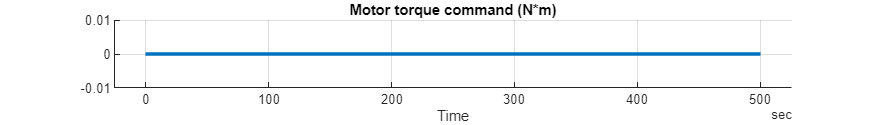

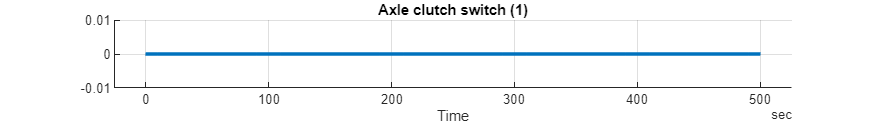

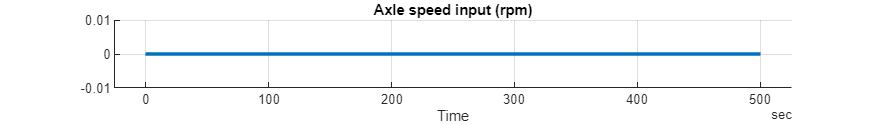

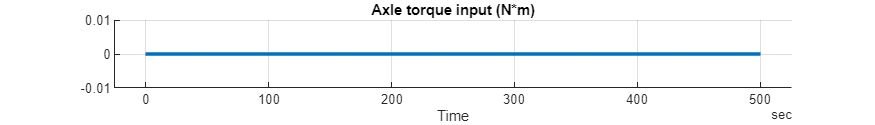

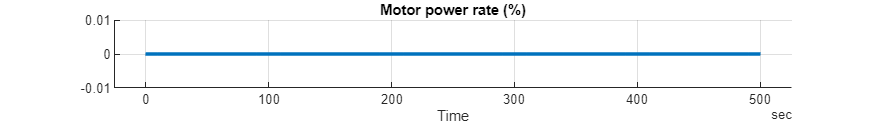

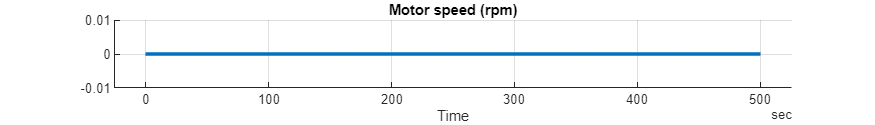

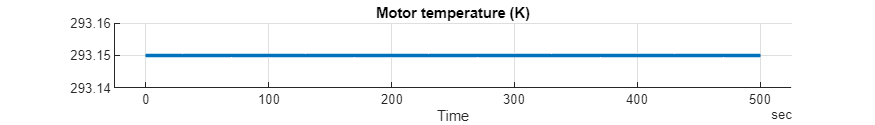

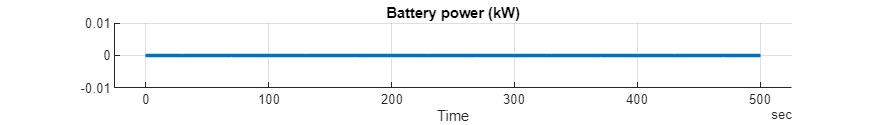

simData = extractTimetable(simOut.logsout);

MotorDriveUnit_Component_plotResults(SimData = simData, FigureHeight = 100);

*Copyright 2021-2022 The Mathworks, Inc.*